p = [0.0006	-0.0646	-0.3964]

p =     0.0006   -0.0646   -0.3964



ratios = [.5 1 2 4]

ratios =     0.5000    1.0000    2.0000    4.0000


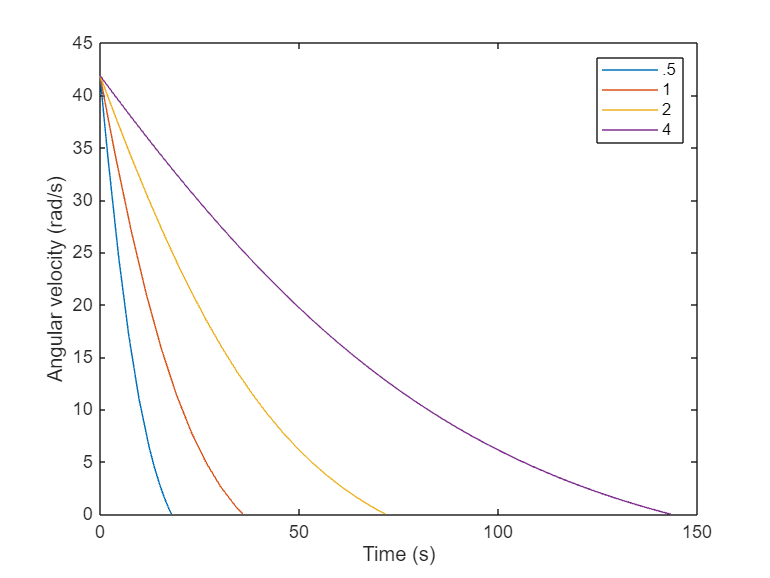


figure;

for ratio = ratios
    f = @(t_in,omega_in) (p(1)*omega_in^2 + p(2)*omega_in + p(3))/ratio;
    [ode45_t_list, ode45_freq_list] = ode45(f, [0, 150], freq_list(1));
    plot(ode45_t_list, ode45_freq_list); hold on;
end

axis([0 150 0 45])
legend('.5', '1', '2', '4')
xlabel("Time (s)")
ylabel("Angular velocity (rad/s)")

p = [0.0006	-0.0646	-0.3964]

p =     0.0006   -0.0646   -0.3964



t_stop_old = 34.43;

t_stop_ratios = zeros(100,1);
rho_ratios = linspace(.1,4,100);

i=1

i = 1

for ratio = rho_ratios
    f = @(t_in,omega_in) (p(1)*omega_in^2 + p(2)*omega_in + p(3))/ratio;
    [ode45_t_list, ode45_freq_list] = ode45(f, [0, 200], freq_list(1));

    %figure;
    %plot(ode45_t_list, ode45_freq_list)
    %axis([0 150 0 40])

    % binary search to find when it reaches 0
    low = 1;
    high = length(ode45_freq_list);
    mid = floor((low+high)/2);
    while true
        mid = floor((low+high)/2);
        mid_val = ode45_freq_list(mid);
        if (mid_val==0 || mid==high || mid==low)
            break;
        elseif mid_val>0
            low = mid;
        else
            high = mid;
        end
    end
    t_stop_ratios(i) = ode45_t_list(mid)/t_stop_old;
    i = i+1;
end

t_stop_ratios

t_stop_ratios =     0.1011
    0.1409
    0.1808
    0.2206
    0.2604
    0.3002
    0.3401
    0.3799
    0.4197
    0.4596


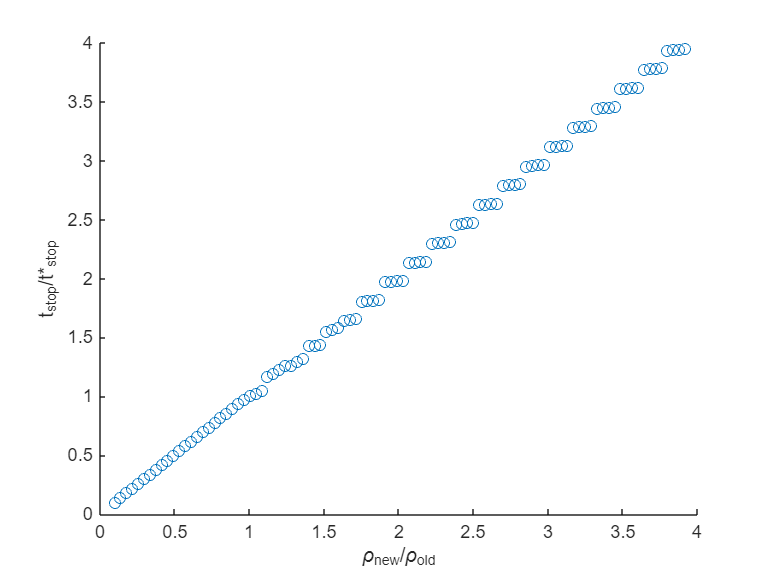

figure;
scatter(rho_ratios, t_stop_ratios); hold on;
xlabel("\rho_{new}/\rho_{old}")
ylabel("t_{stop}/t*_{stop}")
axis([0 4 0 4])